# Dynamic Models for Model Based Control 

**Sachin C. Patwardhan, Anjali P. Deshpande and Sharad Bhartiya **

Dept. of Chemical Engineering,

 Indian Institute of Technology Bombay, Mumbai 400076 India  

## Introduction

Dynamics of processes can be described by different types of models. These models can be quantitative, qualitative or statistical models.  

- Models are extremely important in **Advanced Control Systems** to quantify details about the system before taking any corrective action in a controller, just like a doctor who wants to know the body temperature or blood pressure, before prescribing the treatment for some ailment. 

- Models are also important when we want to  design a  control system  to make the process behave in the desired manner. For example in aerospace domain, control of gas turbine system or control of an aircraft using an autopilot etc. needs mathematical models that capture dynamic or transient behavior of the system and its relationship with inputs. 

- Models are useful in understanding the systems which are not accessible to us, like astronomical models. In the context of advanced control, models are useful for constructing estimates of variable that cannot be measured explicitly, i.e. as soft sensors. 

Models help us to understand the process characteristics like gain or sensitivity w.r.t. inputs at the steady state, time response parameters like settling time and rise time, which are important from controller design point of view.  Variation in the pressure of a gas is very fast, while changes in temperature in a distillation column is very slow. A model helps us to understand this nature of the process and if we know the nature of the transient behaviour we can set the controller parameters in an appropriate manner to achieve the desired performance. 

Thus, if an accurate dynamic model is known, then the controller can be designed using the model to set feasible performance goals. A controller based on a known process models, such as **Model Predictive Control,  **optimizes the control efforts while keeping the process variables and inputs within constraints and thus utilizes the operational envelope of the process for the controller to locate the best operating point.

We begin this lesson with description of different types of dynamic models used in process control. We then proceed  to introduce the theme example of this course, the **Quadruple Tank Process, [1]****.** We will understand how mathematical model is obtained from first principles for the process and understand it's important characteristics including minimum and non-minimum phase operation of the process. 

**Learning Objectives:**

- To learn about different types of models used in model based controllers. 

- To study mechanistic model for the theme example: Quadruple Tank Process 

## Different Mathematical Models

A mathematical model describes behaviour of a real-world system. However, there is always some mismatch between the system and the model. Hence the model has some limitations based on our modeling hypothesis, availability of online computing resources, etc. It quantifies the input/output behavior and you can use it for analysis and simulation of a system without causing any disturbance in the actual system. Different types of mathematical models, commonly used in control systems, are shown in Figure 1 below. Qualitative models, such as signed di-graphs,  qualitative differential equations, qualitative reasoning etc., have been used for process monitoring and fault diagnosis. On the other hand, a vast majority of control system design techniques exclusively rely on quantitative models. An accurate mathematical model can be thought of as a digital twin of the real-world system. Mathematical models can be differentiated from each other based on their structure, the way they are obtained, and the way they are represented. 

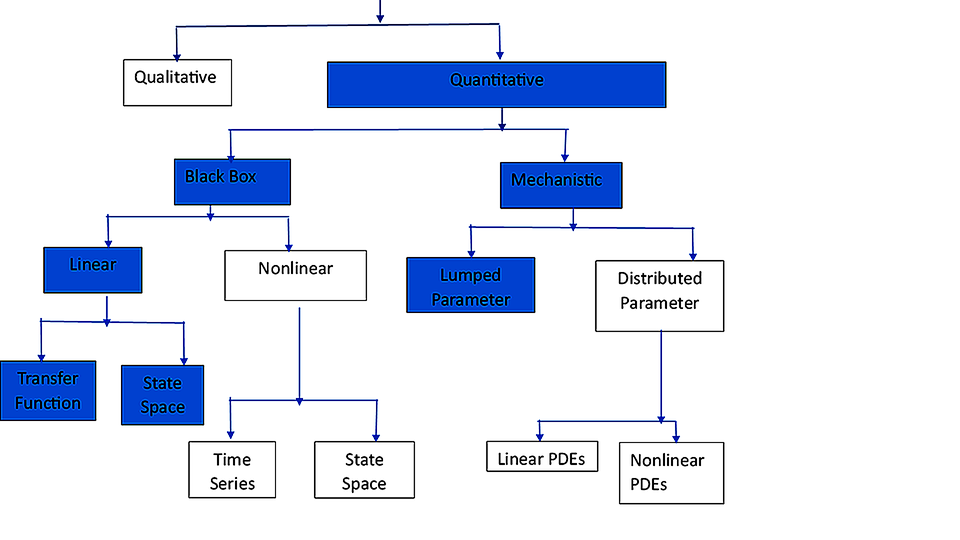

**Figure 1: Different Types of Models**

Since the focus of this course is on Model Predictive Control, we are interested in mathematical models. A **mathematical model** is a description of a system 

- Using mathematical concepts and equations

- It is composed of variables and

- Operators: Algebraic operators, functions, differential operators, etc.

Models can be classified as Mechanistic (or First Principles based) models or Data Driven models. Lumped Parameter Mechanistic  models are often described by  a set of linear or nonlinear ordinary differential equations (ODEs) or differential algebraic equations (DAEs). Since these are derived from the first principles, they are valid over a wide operating range for a given plant/process. They provide physical insights into the internal working of a system. They are also known as  **White Box models **and can be are obtained using 

- Momentum, Energy and Material Balances

- Charge Balance

- Physical Laws, Constitutive Relationships

- Kinetic and Thermodynamic models 

In some cases, a complete description of the process can not be given as per above rules, in such cases **Semi-Phenomenological/ Grey Box Models** are used. Here part of model developed from the first principles and part developed from data. A dynamic model for a reactor using energy and material balances combined with the reaction kinetics modeled using a neural network is an example of a grey box model. It is a better choice than a complete black box model since one can check closure of material and energy balances. 

Development of a mechanistic or a grey box model can be a time consuming process. The development of such models needs a domain expert. Also, for the grey-box model development we have to conduct experiments to generate data needed to  train the neural network. 

 A reliable mechanistic model may not be available for a complex process or may be too time-consuming (and hence expensive) to develop. In such cases, a data driven model can be quickly obtained without using material or energy balances. Such models are called as Black Box models. Such models are obtained by injecting known input perturbations in the system, recording measured outputs generated in response to the perturbations and then estimating dynamic model parameters using optimization. States of such models may not have any physical significance, but represent a quantifiable accurate dynamic relationship between inputs and outputs of a system.   These models are approximate description of the system dynamics and are not as accurate as mechanistic models. The mode accuracy depends on the operating regime in which the system is perturbed to generate the training data, accuracy of measurements and presence of unknown disturbances influencing the process.

The focus of this course in on developing Model Predictive Control schemes using linear dynamic models. Since students with engineering background are familiar with mechanistic models developed using laws of physics, we begin with using a mechanistic dynamic model for controller synthesis. These models typically consist of a set of coupled multi-variable nonlinear ODEs.  The development of control relevant black-box models is introduced in the later part of the course.

## **Quadruple Tank System **

To understand how a typical industrial process behaves, let us  consider a modified version of the Quadruple Tank System by Johansan [1]. It is widely used as a benchmark in process control theory since it is a multivariable process and exhibits a wide-variety of system behaviour. This process has been selected in this course for demonstrating most of the Advanced Process Control concepts and will be a common example throughout the course.  Let us have a look at the dynamical model of this process. 

Consider the Quadruple Tank process as shown in Figure 1.  

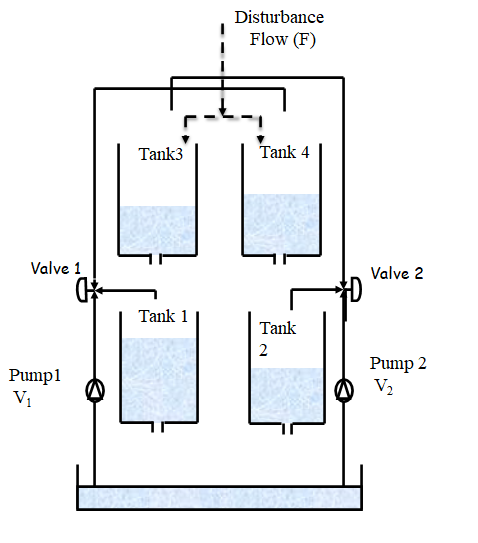

**Figure 1: Schematic of Modified Quadruple Tank Process**

As can be seen in the figure, there are four coupled tanks. Two pumps, which are driven with voltages, $V_1 \;\textrm{and}\;\textrm{V2}$, are used to pump water to the system. These voltage inputs can be considered as the two **manipulated inputs**. In particular, the water from Pump 1 goes through a splitter valve after which part of the flow goes to bottom Tank 1 and the remainder to the top of Tank 4. Similarly, water from Pump 2 is split between Tank 2 and Tank 3. Water from the top Tank 3 and Tank 4 drains to Tank 1 and Tank 2, respectively, thereby making the process highly interactive. Water from Tank 1 and Tank 2 drains to the sump.  At low tank levels, the Q Tank system can exhibit severe non-linearity. It also exhibits both minimum phase as well as non-minimum phase behaviour, just by changing certain parameters. We have modified the original system by including a disturbance flow, F , in Tank 3 and Tank 4. 

The control objective for this process is to **manipulate the flow-rate through Pump 1 and Pump 2 to achieve the desired levels in the Tank 1 and 2 and maintain them in the face of disturbance flow changes.**

How can we do this? To control the level in Tank 1, if we manipulate the **input to control valve 1**, it will also affect the levels in Tank 4 and in turn Tank 2. Similarly if we change the** input to control valve 2**, it will change flows in Tank 2, Tank 3 and Tank 4. So, with any input changes, three levels are affected, exhibiting the interacting nature of the process. Thus it becomes challenging to control the process. In real world industrial processes, there would be multiple interactions and interconnected units. Figure 2 shows a picture of the Quadruple Tank experimental set up developed at IIT Bombay. 

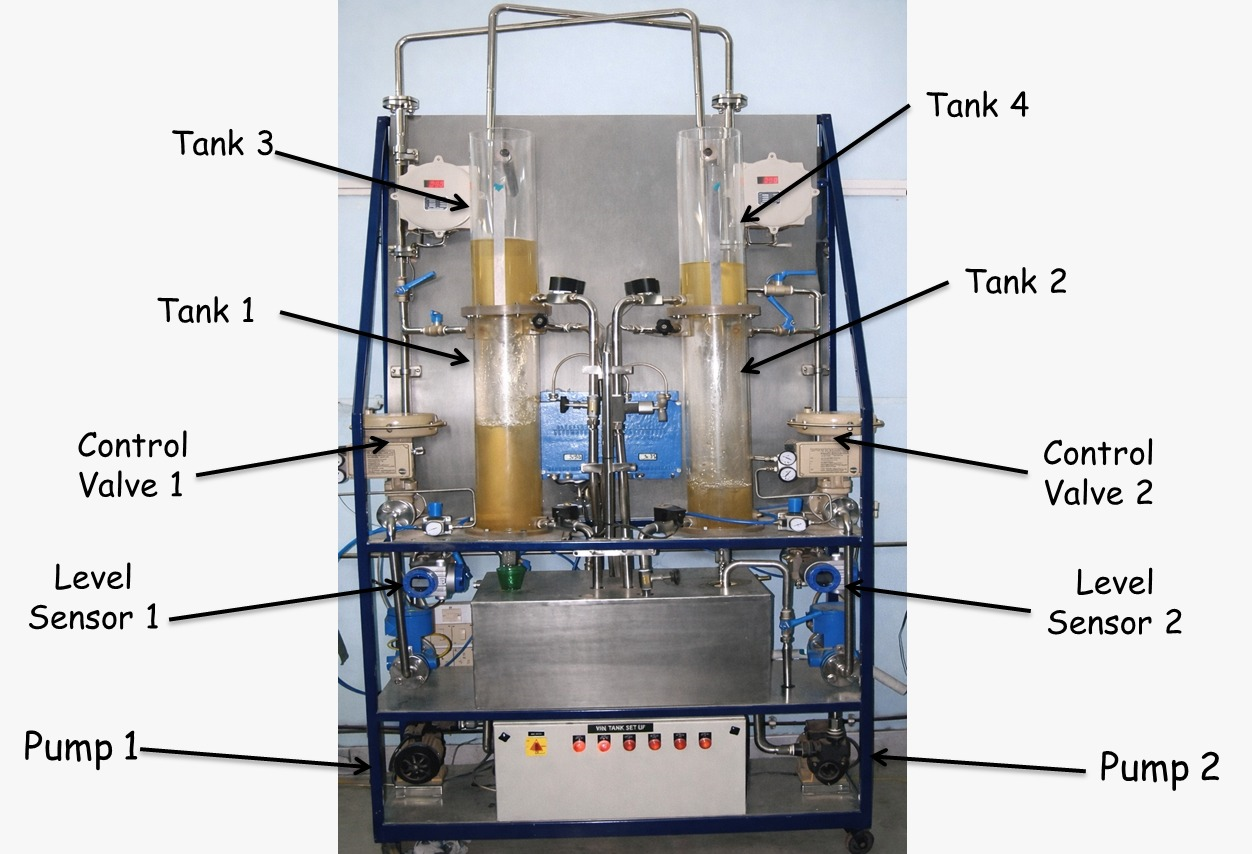

**Figure 2: Laboratory Set-up of Quadruple Tank Process at Automation Lab, IIT Bombay**

### **Model for a Modified Version of Quadruple Tank Process**

Quadruple Tank Process is a multivariable process and exhibits minimum phase/non-minimum phase behaviour, just by changing certain parameters. The first-principles model for the Four Tank System can be developed using material balance along with Torricelli's law. The accumulation of water volume in the four tanks as a result of changing water inlet and outlet flow-rates from the tanks are shown below. 

The unsteady state material balance (or equivalently volume balance owing to in-compressible nature of water) for each Tank can be written as a differential equation,

$\frac{d\left(\textrm{Volume}\right)}{\textrm{dt}}=\textrm{Flow}\;\textrm{In}-\textrm{Flow}\;\textrm{Out}$  -------------(1)

Thus, we can write the material balance for Tank 1, 2, 3 and 4 as follows,

$\begin{array}{l}
A_1 \frac{{d\;h}_1 }{\textrm{dt}}=a_3 \sqrt{2gh_3 }+\left(\gamma_1 \right)k_1 v_1 -a_1 \sqrt{2gh_1 }\\
A_2 \frac{{d\;h}_2 }{\textrm{dt}}=a_4 \sqrt{2gh_4 }+\left(\gamma_2 \right)k_2 v_2 -a_2 \sqrt{2gh_2 }\\
A_3 \frac{{d\;h}_3 }{\textrm{dt}}=\left(1-\gamma_2 \right)k_2 v_2 -a_3 \sqrt{2gh_3 }+\gamma_3 F\\
A_4 \frac{{d\;h}_4 }{\textrm{dt}}=\left(1-\gamma_1 \right)k_1 v_1 -a_4 \sqrt{2gh_4 }+\left(1-\gamma_3 \right)F
\end{array}$-------------(2)

Note that $0<\gamma_i <1$ for i = 1,2,3 are fractions and indicate the splits of the flows going to different tanks. To understand the above set of equations, let us consider the terms in the Tank 1 dynamics,

 $A_1 \frac{{d\;h}_1 }{\textrm{dt}}=\;a_3 \sqrt{2gh_3 }+\left(\gamma_1 \right)k_1 v_1 -a_1 \sqrt{2gh_1 }$.   ------(3)

Here, 

$A_1 \frac{{d\;h}_1 }{\textrm{dt}}=\frac{d\left(A_1 h_1 \right)}{\textrm{dt}}=\frac{d\left(\textrm{Volume}\right)}{\textrm{dt}}=F_{3,\textrm{out}} +$$F_{\textrm{in},1}$- $F_{1,\textrm{out}}$  ------(4)

where $A_1$ is the cross-section area of the first tank. Thus, the derivatives on the LHS of each equation represents the rate of change of liquid volume in the tank. The first term on the RHS, i.e. $F_{3,\textrm{out}} =a_3 \sqrt{2gh_3 }$ represents the flow of liquid out of Tank 3 that is an input to Tank 1. It is proportional to the square-root the level in Tank 3 and the cross section area of the tank outlet at the bottom of the tank. The square-root relation is due to Torricelli's law. The second term $F_{\textrm{in},1} =\left(\gamma_1 \right)k_1 v_1$ represents the inflow to Tank 1 from Pump 1. Here, $v_1$ is the voltage input to Pump 1, $k_1$ is the proportionality constant, $k_1 v_1$`represents total flow of fluid pumped by Pump 1, and $\left(\gamma_1 \right)$ represents the fraction of the Pump 1 flow that enters Tank 1.  The third term, $F_{1,\textrm{out}} =a_1 \sqrt{2gh_1 }$ represents fluid out-flow from the bottom of Tank 1. The disturbance flow F enters Tank 3 and Tank 4. Parameter $\gamma_3$ represents fraction of F that enters Tank 3 and the rest enters Tank 4. Thus, the model parameter $\;\gamma_2$ represent ratio of inflow to from Pump 2 to Tank 2 while remaining fraction goes to Tank 3. Parameters $k_i :i=1,2$ represent the voltage to flow conversion parameter for $i^{\textrm{th}}$ pump and $a_i :i=1,2,3,4$ represent cross sectional areas of the outlet pipes at the bottom of $i^{\textrm{th}}$ tank. 

**Table 1: Quadruple Tank Model Parameters**

As we can observe from the equations, change in input $v_1$ directly influences level in Tank 1, and through Tank 4 level indirectly influences level in Tank 2. Similarly, change in input $v_2$ directly influences level in Tank 2, and through Tank 3 level indirectly influences level in Tank 1. Thus, this system belongs to class of Multiple Input Multiple Output (MIMO) systems. Thus, if it is desired to use a PID controller to control level in Tank 1, then it is not obvious whether we should manipulate $v_1$ or $v_2$ using the controller.  

### **Dynamic Model as Ordinary Differential Equation Initial Value Problem (ODE-IVP)**

Thus, defining the state and input vectors as 


$$X\left(t\right)={\left\lbrack h_1 \left(t\right)\;{\;h}_2 \left(t\right)\;{\;h}_3 \left(t\right)\;{\;h}_4 \left(t\right)\right\rbrack }^T \;,\;\;\;\;U\left(t\right)={\left\lbrack v_1 \left(t\right)\;{\;v}_2 \left(t\right)\right\rbrack }^T \;\;\;\textrm{and}\;\;D\left(t\right)=F\left(t\right)$$


 we can now write the ODE-IVP in a succinctly as

 $\frac{\textrm{dX}}{\textrm{dt}}=f\left(X\left(t\right),U\left(t\right),D\left(t\right)\right)$ ------(5)

where the four material balances can be expressed using the vector-matrix notations as follows:

$\frac{\textrm{dX}}{\textrm{dt}}=\frac{d}{\textrm{dt}}\left\lbrack \begin{array}{c}
h_1 \\
h_2 \\
h_3 \\
h_4 
\end{array}\right\rbrack =\left\lbrack \begin{array}{c}
-\frac{a_1 }{A_1 }\sqrt{2gh_1 }+\frac{a_3 }{A_1 }\sqrt{2gh_3 }+\frac{\gamma_1 k_1 }{A_1 }v_1 \\
-\frac{a_2 }{A_2 }\sqrt{2gh_2 }+\frac{a_4 }{A_2 }\sqrt{2gh_4 }+\frac{\gamma_2 k_2 }{A_2 }v_2 \\
-\frac{a_3 }{A_3 }\sqrt{2gh_3 }+\frac{\left(1-\gamma_2 \right)k_2 }{A_3 }v_2 +\frac{\gamma_3 }{A_3 }F\\
-\frac{a_4 }{A_4 }\sqrt{2gh_4 }+\frac{\left(1-\gamma_1 \right)k_1 }{A_4 }v_1 +\frac{\left({1-\gamma }_3 \right)}{A_3 }F
\end{array}\right\rbrack =\left\lbrack \begin{array}{c}
f_1 \left(X,\;U,D\right)\\
f_2 \left(X,\;U,D\right)\\
f_3 \left(X,\;U,D\right)\\
f_4 \left(X,\;U,D\right)
\end{array}\right\rbrack$--------------(6)

To completely define the system dynamics, we additionally need ***t***o specify the initial conditions for the state variables $t=0$, i.e. $X\left(0\right)$.  

$h_1 \left(t=0\right)=h_{10} ,h_2 \left(t=0\right)=h_{20} ,h_3 \left(t=0\right)=h_{30} ,h_4 \left(t=0\right)=h_{40}$  ------(7)


$$X\left(0\right)={\left\lbrack h_{10} \;{\;h}_{20} \;{\;h}_{30} \;{\;h}_{40} \right\rbrack }^T$$


Such dynamic models are referred to as ODE initial value problem (ODE-IVP). Note that specifying the four levels in the tank completely specifies the **"state"** of the system. In systems theory parlance, we refer to the dependent variables that completely specify the state of the system as the "state vector" .  

  The quadruple tank exhibits two distinctly different dynamic behavior  under the following two scenarios:

**Scenario A:** $\gamma_1 >0\ldotp 5\;\textrm{and}\;\;\gamma_2 >0\ldotp 5\;$ i.e. when the direct flows to Tank 1 and Tank 2  are larger than flows to Tank 3 and Tank 4  

**Scenario B:** $\gamma_1 <0\ldotp 5\;\textrm{and}\;\;\gamma_2 <0\ldotp 5\;$ i.e. when the direct flows to Tank 1 and Tank 2  are smaller than flows to Tank 3 and Tank 4 

### Dynamic Simulation under Constant Inputs 

Now, given an initial condition and inputs defined over interval $\left\lbrack 0,t_f \right\rbrack$, we can solve the ODEs using a numerical method such as explicit Euler or Runge-Kutta method and simulate dynamic behavior of the system. Let us assume that the inputs are held constant at some specified values and simulate system dynamics starting from different initial conditions for these two scenarios: 

clear all 
close all

% Declare global variables needed to communicate data between the main
% program and functions 

global QTank U_k D_k

% Four Tank system: Initialize model parameters

QTank.a1 = 0.071 ;    % cm^2 (Area of outlet tube for Tank 1)
QTank.A1 = 28    ;    % cm^2 (Area of tank 1)

QTank.a3 = 0.071 ;    % cm^2 (Area of outlet tube for Tank 3)
QTank.A3 = 28    ;    % cm^2 (Area of tank 3)

QTank.a2 = 0.057 ;    % cm^2 (Area of outlet tube for Tank 2)
QTank.A2 = 32    ;    % cm^2 (Area of tank 2)

QTank.a4 = 0.057 ;    % cm^2 (Area of outlet tube for Tank 4)
QTank.A4 = 32    ;    % cm^2 (Area of tank 4)

**Task 1: **Select the operating point corresponding to scenario A or B**.  **Model parameters at Scenario A (minimum phase (P-)) or Scenario B (non-minimum phase (P+)) operating points will be loaded in the workspace.

% Model parameters at Scenario A (minimum phase (P-)) and 
% Scenario B (non-minimum phase (P+)) operating points

operating_pt = 2;

if ( operating_pt == 1 )                % Scenario A
    QTank.gam1 = 0.7 ;    % cm^3/Vs
    QTank.k1 =   3.33 ;    
    QTank.gam2 = 0.6 ;    % cm^3/Vs
    QTank.k2 =   3.35 ;
    QTank.Us = [ 3 3 ]' ;           % Steady state input 
elseif ( operating_pt == 2 )        % Scenario B
    QTank.gam1 = 0.43 ;    % cm^3/Vs
    QTank.k1 =   3.14 ;
    QTank.gam2 = 0.34 ;    % cm^3/Vs
    QTank.k2 =   3.29 ;
    QTank.Us = [ 3.15 3.15 ]' ;   % Steady state input 
end 
QTank.Ds = 1 ;    % Steady state disturbance flow input 
QTank.gam3 = 0.4 ;   % For disturbance input 

U_k = QTank.Us ;  D_k = QTank.Ds ;  % Hold inputs constant 

QTank.samp_T = 4 ;   % Set Interval of integration 

N = 151 ;      % Simulation run time

n_st = 4 ;   % State vector dimension 

Xk = zeros(n_st,N); % create a matrix to save state sequence in time   


**Task 2:** Specify initial condition away from the steady state. 

x0(1) = -1;  x0(2) = 0.5;
x0(3) =-1.25;  x0(4) =1.25; 

Xk(:,1) = [ 13 14 5 6 ]'+ x0' ; % Specify an initial state
disp(Xk(:,1)')   % Display initial state 

   1.2000e+01   1.4500e+01   3.7500e+00   7.2500e+00



**Task 3:** To solve the differential equations online, there are multiple options for the solver. **User can select any solver as per their choice.**

 Choice of ODE Solver (1) for Explicit Euler OR (2) for Runge Kutta 

Open loop process simulation is done using for-loop for $\textrm{kT}=0,T,\ldotp \ldotp \ldotp \ldotp ,\left(N-1\right)T$

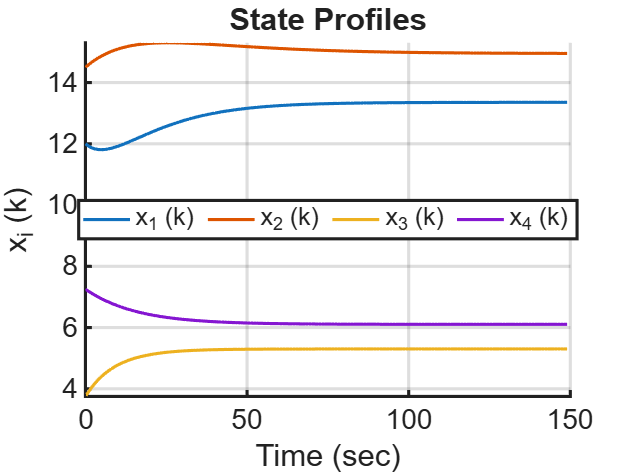

% Open loop simulation using for-loop for kT = 0,T,....,(N-1)T

ODE_solver = 1;

for k = 1:N-1

    kT(k) = (k-1);

    % Quadruple Tank Plant Simulation from sampling instant k to k+1 using nonlinear ODE model

    if (ODE_solver == 1 )
        Xk(:,k+1) = Xk(:,k) + QTank.samp_T * QTank_Dynamics(kT(k)*QTank.samp_T, Xk(:,k))  ;  % Explicit Euler solver
    else
        [T,Xt] = ode45( @QTank_Dynamics, [ 0 QTank.samp_T ], Xk(:,k)) ; % Rungee-Kutta variable step-size solver 
        Xk(:,k+1) = Xt( end,: )';
    end

end

kT(N) = N-1 ;

The following MATLAB function calculates derivatives for specified $\left(X\left(k\right),U\left(k\right),D\left(k\right)\right)$   

% Modified Quadruple Tank System  
% Ref.:  Johanson, K. H. IEEE Trans. On Control Systems Technology, Vol. 8, No. 3, May 2000
% Function called by ODE solver for Dynamic Simulation 
% Given (X(t),U(k),D(k)) this function computes derivative f(X(t),U(k),D(k)) 

function Xdot = QTank_Dynamics(time, Xt)

global QTank U_k D_k

gc = 981 ;  % (cm/s^2) gravitational constant 

h(1) = Xt(1) ; h(2) = Xt(2) ; h(3) = Xt(3) ; h(4) = Xt(4) ;

hdot(1) = -(QTank.a1 / QTank.A1) * (2 * gc * h(1))^0.5 ;
hdot(1) = hdot(1) + (QTank.a3 / QTank.A1) * (2 * gc * h(3))^0.5 ;
hdot(1) = hdot(1) + (QTank.gam1 * QTank.k1 / QTank.A1) * U_k(1) ;

hdot(2) = -(QTank.a2 / QTank.A2) * (2 * gc * h(2))^0.5 ;
hdot(2) = hdot(2) + (QTank.a4 / QTank.A2) * (2 * gc * h(4))^0.5 ;
hdot(2) = hdot(2) + (QTank.gam2 * QTank.k2 / QTank.A2) * U_k(2) ;

hdot(3) = -(QTank.a3 / QTank.A3) * (2 * gc * h(3))^0.5 ;
hdot(3) = hdot(3) + ((1-QTank.gam2)*QTank.k2 / QTank.A3) * U_k(2) ;
hdot(3) = hdot(3) + (QTank.gam3/ QTank.A3) * D_k  ;
hdot(4) = -(QTank.a4 / QTank.A4) * (2 * gc * h(4))^0.5 ;

   1.3355e+01   1.4948e+01   5.2997e+00   6.1041e+00



hdot(4) = hdot(4) + ((1-QTank.gam1) * QTank.k1 / QTank.A4) * U_k(1) ;
hdot(4) = hdot(4) + ((1-QTank.gam3)/ QTank.A4) * D_k  ;
Xdot = hdot' ;

   3.8223e-04
  -5.2711e-03
   2.9165e-07
  -6.0376e-05



end

**Display Simulation Results **

Set_Graphics_Parameters ;   % This script file sets font size and line thickness for figures 

figure(1), 
plot(kT, Xk(1,:), kT, Xk(2,:), kT, Xk(3,:), kT, Xk(4,:)), grid
xlabel('Time (sec)'), ylabel('x_i (k)')
title('State Profiles')
legend('x_1 (k)', 'x_2 (k)', 'x_3 (k)', 'x_4 (k)', 'location', 'best',Orientation='horizontal')

You will notice that, irrespective of the initial condition that we start with, the states reach identical final values, say $X\left(k\right)=X_s$,  after about 80 samples and continue to remain at $X_s$. This is a steady state or equilibrium point of the system where the time derivatives are zero. Alternate approach to find a steady state is to solve for four coupled algebraic equations 

$\frac{\textrm{dX}}{\textrm{dt}}=f\left(X_s ,U_s ,D_s \right)=\bar{0}$  ------(8)

% Find Equilibrium/ Steady State Operating Point for the specified inputs 

if ( operating_pt == 1 )                           % Scenario A           
   Xs0 = [ 12.4 12.7 1.8 1.4 ]' ;    % Initial Guess 
elseif ( operating_pt == 2 )                    % Scenario B
   Xs0 = [ 12.6 13 4.8 4.9 ]' ;       % Initial Guess
end  
oldopts = optimset ; tolerance = 1e-10 ;
options = optimset(oldopts,'MaxIter', 1e6, 'Display','off', 'TolFun',tolerance, 'TolX', tolerance) ;
QTank.Xs = fsolve(@QTank_Steady_State, Xs0, options ) ;
display(QTank.Xs')

Let us examine whether this steady state is identical to the steady state reached through dynamic simulation we have carried out. The quantity (QTank.Xs - Xk(:,N)) indicates how close Xk(:,N) has reached to the steady state.   

format short e 
display(QTank.Xs - Xk(:,N))  

The following function is required to communicate nonlinear algebraic equations to nonlinear equation solver function ***fsolve *** in MATLAB Optimization Toolbox.  

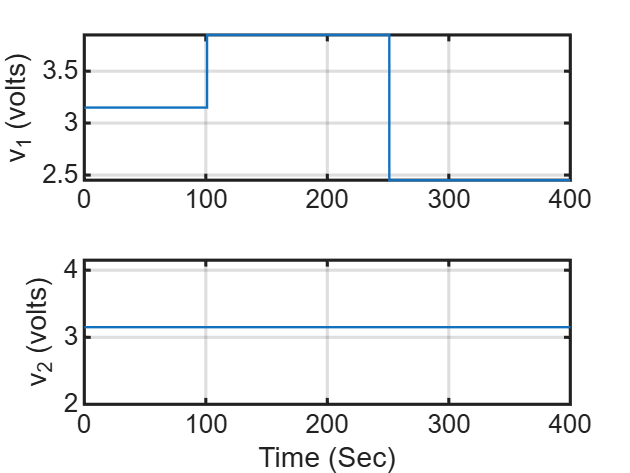

% Modified Quadruple Tank System  
% Ref.:  Johanson, K. H. IEEE Trans. On Control Systems Technology, Vol. 8, No. 3, May 2000
% Function called by ODE solver for Dynamic Simulation 
% Given guess for steady state solution Xs this function computes function vector f(Xs,Us,Ds) 

function fofX = QTank_Steady_State( Xs )

global QTank U_k D_k

gc = 981 ;  % (cm/s^2) gravitational constant 

h(1) = Xs(1) ; h(2) = Xs(2) ; h(3) = Xs(3) ; h(4) = Xs(4) ;

fofX(1) = -(QTank.a1 / QTank.A1) * (2 * gc * h(1))^0.5 ;
fofX(1) = fofX(1) + (QTank.a3 / QTank.A1) * (2 * gc * h(3))^0.5 ;
fofX(1) = fofX(1) + (QTank.gam1 * QTank.k1 / QTank.A1) * U_k(1) ;

fofX(2) = -(QTank.a2 / QTank.A2) * (2 * gc * h(2))^0.5 ;
fofX(2) = fofX(2) + (QTank.a4 / QTank.A2) * (2 * gc * h(4))^0.5 ;
fofX(2) = fofX(2) + (QTank.gam2 * QTank.k2 / QTank.A2) * U_k(2) ;

fofX(3) = -(QTank.a3 / QTank.A3) * (2 * gc * h(3))^0.5 ;

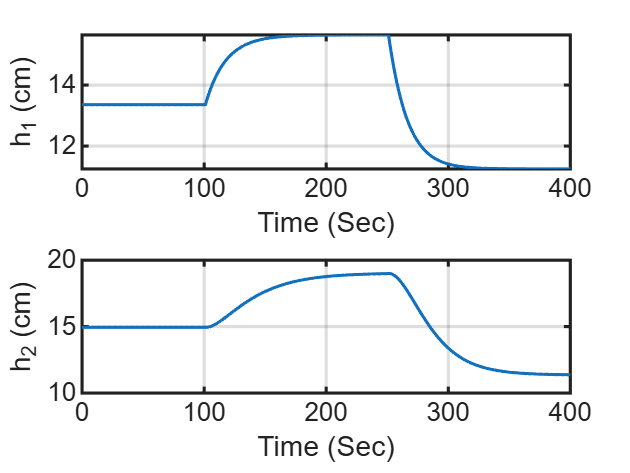

fofX(3) = fofX(3) + ((1-QTank.gam2)*QTank.k2 / QTank.A3) * U_k(2) ;
fofX(3) = fofX(3) + (QTank.gam3/ QTank.A3) * D_k  ;

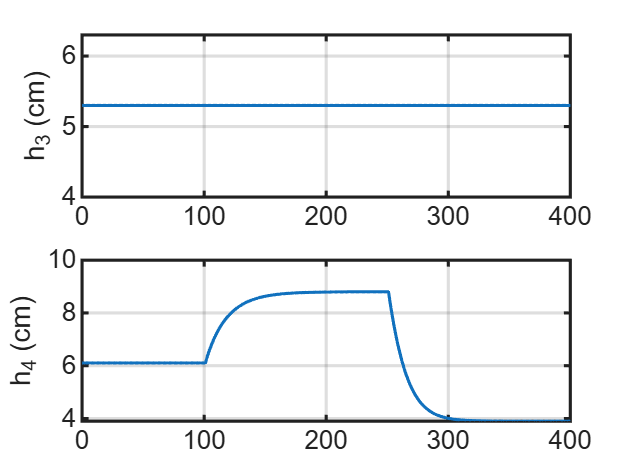

fofX(4) = -(QTank.a4 / QTank.A4) * (2 * gc * h(4))^0.5 ;
fofX(4) = fofX(4) + ((1-QTank.gam1) * QTank.k1 / QTank.A4) * U_k(1) ;

fofX(4) = fofX(4) + ((1-QTank.gam3)/ QTank.A4) * D_k  ;
fofX = fofX' ;
end

### Dynamic Simulation under Input Step Changes 

Now, let us examine dynamic simulations when step changes are introduced in the system in the system, which is initially operating at a steady state operating point. We introduce a sequence of +ve and -ve step change in one input at a time and observe the step response.  

N = 401 ;  
n_st = length(QTank.Xs) ;  % State vector dimension 

gain_mat_p =    3.2663e+00            0
   5.7531e+00   3.8532e+00


n_ip = length(QTank.Us) ;

Xk = zeros(n_st,N); % create a matrix to save state sequence in time   
Xk(:,1) = QTank.Xs ; 

gain_mat_n =    3.0087e+00            0
   5.1015e+00   3.1510e+00



input_no = 1; 

Uk = [ QTank.Us(1)*ones(1,N) ; QTank.Us(2)*ones(1,N) ]  ; % Steady state inputs 

**Task 4:** Specify Step Amplitude such as +/-0.5, 1,1.5 etc, to be given to the selected input. Now observe the input and output wave-forms

step_magnitude=0.7 ;
p_step_change = step_magnitude * ones(1,150) ;
uk_pert = [zeros(1,101) p_step_change -p_step_change ] ;

% Open loop simulation using for-loop for step changes (one at a time)

if (input_no == 1)
    Uk(1,:) = Uk(1,:) + uk_pert ;
else
    Uk(2,:) = Uk(2,:) + uk_pert ;
end 

**Task 5: **Choice of ODE Solver (1) for Explicit Euler OR (2) for Runge Kutta 

ODE_solver = 1;

for k = 1:N-1

    kT(k) = (k-1);

    % Specify input at instant k 

    U_k = Uk(:,k) ; 

    % Quadruple Tank Plant Simulation from sampling instant k to k+1 using nonlinear ODE model

    if (ODE_solver == 1 )
        Xk(:,k+1) = Xk(:,k) + QTank.samp_T * QTank_Dynamics(kT(k)*QTank.samp_T, Xk(:,k))  ;  % Explicit Euler solver
    else
        [T,Xt] = ode45( @QTank_Dynamics, [ 0 QTank.samp_T ], Xk(:,k)) ; % Runga-Kutta variable step-size solver 
        Xk(:,k+1) = Xt( end,: )';
    end

end
kT(N) = N-1 ;

figure(2), subplot(211), stairs( kT, Uk(1,:),LineWidth=1.5), ylabel('v_1 (volts)'), grid
figure(2), subplot(212), stairs( kT, Uk(2,:), LineWidth=1.5), ylabel('v_2 (volts)'), xlabel('Time (Sec)'), grid
figure(3), subplot(211), plot(kT, Xk(1,:)), ylabel('h_1 (cm)'), xlabel('Time (Sec)'),  grid
subplot(212), plot(kT, Xk(2,:)), ylabel('h_2 (cm)'), xlabel('Time (Sec)'), grid
figure(4), subplot(211), plot(kT, Xk(3,:)), ylabel('h_3 (cm)'), grid
subplot(212), plot(kT, Xk(4,:)), ylabel('h_4 (cm)'), grid


What do we observe? Both the levels in Tank 1 and Tank 2  change in response to either step change in $v_1 \;\textrm{or}\;v_2$. This indicates the interactive nature of the process. Here change in any input one of the inputs is causing change in both the outputs, $h_1 \;\textrm{and}\;h_2$. 

Let us estimate steady state gain matrices for +ve and -ve step changes numerically. Steady state gain relating state $i$ and input $j$ is found as follows

$k_{\mathrm{ij}} =\frac{{\mathrm{Xk}}_i \left(\mathrm{initial}\right)-{\mathrm{Xk}}_i \left(\mathrm{final}\right)}{{\mathrm{Uk}}_j \left(\mathrm{initial}\right)-{\mathrm{Uk}}_j \left(\mathrm{final}\right)}$  ------(9)

Steady State Gain Matrix estimate for positive step change 

% Steady State Gain Matrix estimate for positive step change 
gain_vec_p = (1/step_magnitude) * (Xk(:,245) - Xk(:,1)) ;
gain_mat_p = reshape(gain_vec_p,2,2)

Steady State Gain Matrix estimate for negative step change 

% Steady State Gain Matrix estimate for negative step change 
gain_vec_n = (-1/step_magnitude) * (Xk(:,end) - Xk(:,1)) ;
gain_mat_n = reshape(gain_vec_n,2,2)

By trying different values of the step magnitude, we find that 

- The differential equation model for the Quadruple Tank Process is nonlinear. Hence, equal change in inputs, does not give equal change in outputs, as in the linear case. 

- The difference between two gain matrices increases with increase in the step magnitude. This is because the nonlinear effects increase with increase in the step magnitude.

- For Scenario A, Gain relating ${\;h}_1 -u_1$  > Gain relating ${\;h}_2 -u_1$ and for Scenario B. Gain relating ${\;h}_2 -u_1$  > Gain relating ${\;h}_1 -u_1$. This is because of the differences in the flow splits in these two scenarios. In Scenario B, larger fraction of flow goes to the top tanks when compared to the bottom tanks, which makes it harder to control than Scenario A. 

## Transfer Function Models and Multivariable Zeros 

Now, in the first course in control systems, we learn how to linearize a set of nonlinear ODEs in the neighborhood of a steady state operating point and derive transfer function model for the system. You can also read Lesson 2 in Module 2 to refresh your knowledge or refer to Johanson [1] for details. Transfer function models obtained  at the following two steady state operating points 

**Scenario A:**  $X_s =\left\lbrack \begin{array}{cccc}
13\ldotp 1699 & 14\ldotp 5390 & 1\ldotp 9753 & 2\ldotp 0297
\end{array}\right\rbrack$             

**Scenario B: **$X_s =\left\lbrack \begin{array}{cccc}
13\ldotp 3553 & 14\ldotp 9479 & 5\ldotp 2997 & 6\ldotp 1041
\end{array}\right\rbrack$  

are of particular interest in this course. Since there are 2 inputs and 2 outputs, we get a $2\times 2$ transfer function matrix. The general form for the transfer function matrix derived from the Linearized Mechanistic model above is given as follows [1]: 

$G\left(s\right)=\left\lbrack \begin{array}{cc}
\frac{\gamma_1 c_1 }{1+T_1 s} & \frac{\left({1-\gamma }_2 \right)c_1 }{\left(1+T_3 s\right)\left(\left(1+T_1 s\right)\right)}\\
\frac{\left({1-\gamma }_1 \right)c_2 }{\left(1+T_4 s\right)\left(\left(1+T_2 s\right)\right)} & \frac{\gamma_2 c_2 }{1+T_2 s}
\end{array}\right\rbrack$  ------------(10)

where

$c_1 =\frac{T_1 k_1 k_c }{A_1 }$ ,  $c_2 =\frac{T_2 k_2 k_c }{A_2 }$   and   $T_i =\frac{A_i }{a_i }\sqrt{\frac{2h_{i,s} }{g}\;}$  $\textrm{for}\;i=1\ldotp \ldotp \ldotp 4$   ------(11)

For the two operating points Scenario A and Scenario B  we have the following time constants. 

Thus the dominating time constants are thus similar for both operating conditions. 

**Transfer function matrix for Scenario A**  

$G_- \left(s\right)=\left\lbrack \begin{array}{cc}
\frac{2\ldotp 6}{1+62s} & \frac{1\ldotp 5}{\left(1+23s\right)\left(\left(1+62s\right)\right)}\\
\frac{1\ldotp 4}{\left(1+30s\right)\left(\left(1+90s\right)\right)} & \frac{2\ldotp 8}{1+90s}
\end{array}\right\rbrack$     ------------(12)

**Transfer function matrix for Scenario B**

$G_+ \left(s\right)=\left\lbrack \begin{array}{cc}
\frac{1\ldotp 5}{1+63s} & \frac{2\ldotp 5}{\left(1+39s\right)\left(\left(1+63s\right)\right)}\\
\frac{2\ldotp 5}{\left(1+56s\right)\left(\left(1+91s\right)\right)} & \frac{1\ldotp 6}{1+91s}
\end{array}\right\rbrack$     -------------(13)

### Interpretation of Multivariable Zeros [1]

Zero of MIMO transfer function are roots of the numerator polynomial of the rational transfer function described by [1]

 
$$\textrm{de}t\;\left(G\left(s\right)\right)=\frac{c_1 c_2 }{\gamma_1 \gamma_2 \prod_{i=1}^4 \left(1+T_i s\right)}\left\lbrack \left(1+T_3 s\right)\left(1+T_4 s\right)-\frac{\left(1-\gamma_q \right)\left(1-\gamma_2 \right)}{\gamma_1 \gamma_2 }\right\rbrack$$


 The transfer matrix given in equation (10), thus has two finite zeros for $\gamma_1 ,\gamma_2 \in \left(0,1\right)$. One of them is always in the left half-plane, but the other can be located either in the left or the right half-plane.  Introduce a parameter $\eta \in \left(0,\infty \right)$ such that

$\eta =\frac{\left(1-\gamma_1 \right)\left(1-\gamma_2 \right)}{\gamma_1 \gamma_2 }\Longrightarrow \eta -1=\frac{1-\left(\gamma_1 {+\gamma }_2 \right)}{\gamma_1 \gamma_2 }$  ------(14)

the numerator polynomial becomes

$T_3 T_4 \;s^2 +\left(T_3 +T_4 \right)s+1-\eta =0$    ------(15)

which has two roots

$z_1 =\frac{-\left(T_3 +T_4 \right)-\sqrt{{\left(T_3 +T_4 \right)}^2 -4T_3 T_4 \left(1-\eta \right)}}{2T_3 T_4 }\;\;\textrm{and}\;\;\;z_2 =\frac{-\left(T_3 +T_4 \right)+\sqrt{{\left(T_3 +T_4 \right)}^2 -4T_3 T_4 \left(1-\eta \right)}}{2T_3 T_4 }$  ------(16)

 If $\eta$ is small, the two zeros are close to $-\frac{1}{T_3 }$, $-\frac{1}{T_4 }$ respectively. Furthermore, $z_1$ tends to $-\infty$ and $z_2$ zero tends to $+\infty$ as $\eta \to \infty$. If  $\eta =1$, then one zero is located at the origin. This case corresponds to  $\gamma_1 +\gamma_2 =1$. Now, when 

${0<\gamma }_1 +\gamma_2 <1\Longrightarrow \eta -1>0$    ------(17)

and

 $\sqrt{{\left(T_3 +T_4 \right)}^2 +4T_3 T_4 \left(\eta -1\right)}-\left(T_3 +T_4 \right)>0$   and   $-\left(T_3 +T_4 \right)-\sqrt{{\left(T_3 +T_4 \right)}^2 +4T_3 T_4 \left(\eta -1\right)}<0$   ------(18)

Thus, it follows that for **Scenario B the system has one zero is in RHP of s-plane and one in LHP of s-plane**. On the other hand when 

${1<\gamma }_1 +\gamma_2 <2\Longrightarrow \eta -1<0$  ------(19)

and 

 $\sqrt{{\left(T_3 +T_4 \right)}^2 +4T_3 T_4 \left(\eta -1\right)}-\left(T_3 +T_4 \right)<0$   and   $-\left(T_3 +T_4 \right)-\sqrt{{\left(T_3 +T_4 \right)}^2 +4T_3 T_4 \left(\eta -1\right)}<0$  ------(20)

i.e.** both zeros in the LHP of the s-plane phase for Scenario A**.  Thus, under Scenario A, the MIMO system exhibits ***minimum phase behavior*** and Scenario B the system exhibits ***non-minimum phase behavior***. In the rest of the course, the operating point that corresponds to Scenario A is referred to as **Minimum Phase Operating Point** and  the operating point that corresponds to Scenario B is referred to as **Non-Minimum Phase Operating Point. **

 An important difference between scalar systems and multivariable systems is that not only the location of a multivariable zero is important but also its direction. When a MIMO system has a transmission zero at $s=z$, then the input in certain direction, say $u_0$,  and initial condition can create a mode of internal dynamic activity that is completely invisible at the outputs. At frequency $s=z$, sinusoidal inputs in the direction $u_0$ are completely blocked from reaching the output. In other words, the zero corresponds to an internal mode---the zero dynamics---that is excited but not observable through the outputs. In the quadruple-tank system, the physical origin of the transmission zero is a conflict between two signal pathways. Each input reaches each output via a direct fast path (through the lower tank) and an indirect slow path (through the upper tank). At the transmission zero frequency, contributions from these two paths arrive at the output with equal magnitude but opposite sign, causing perfect cancellation. Because the zero direction is invisible to the controller via the output, no feedback can detect or correct the corresponding internal motion. Right-half-plane (RHP) zeros therefore impose hard, controller-independent fundamental limitations on achievable closed loop performance. Also if  $\gamma_1$ is small, then zero is mostly associated with the first output. If  $\gamma_1$ is close to one, then the zero is mostly associated with the second output. Hence, for a given zero location, the relative size of  $\gamma_1$ and $\gamma_2$ determines which output the right half-plane zero is related to. 

Non-minimum phase (NMP) systems are difficult to control primarily due to their **inverse response** (ref. **Appendix**) and the **fundamental limitations** imposed by right-half plane (RHP) zeros. When a control input is applied, the system output initially moves in the opposite direction of the desired steady state, which is non-intuitive. A controller unaware of this system characteristics can start planning input moves in wrong directions. Model based controllers like, MPC or LQOC, attempt  to cancel the system's  dynamics through inversion. Canceling an RHP zero requires creating  an unstable pole in the controller, leading to an internally unstable closed-loop system. Thus, systems with non-minimum phase zero are inherently difficult to control.  

## Simulink Model

Reader can also understand the dynamics of Q tank process(discussed in the three lessons) from the Simulink model

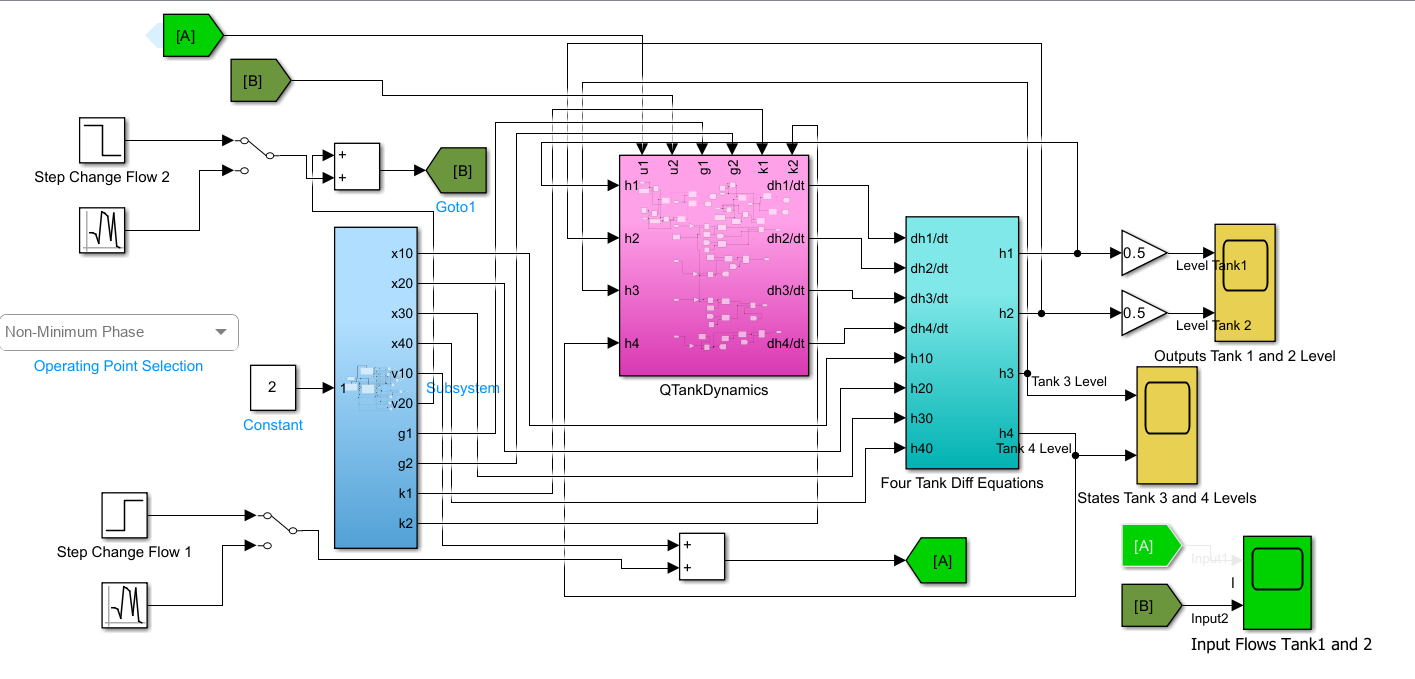

[**Click here to open the Simulink model**](matlab:open('./fourtank_OpenloopModel.slx'))

## Conclusion

In this lesson, we have presented a mechanistic (first-principles based)  nonlinear model for the benchmark Quadruple Tank process, which is a multivariable system. This system is used as a theme example to illustrate various concepts in this course. This system is interesting because it exhibits multi-variable interactions and mildly nonlinear dynamic behavior. Under certain operating conditions, it can exhibit non-minimum phase characteristics, which makes the control task difficult due to presence of RHP transmission zero and inverse response characteristics.  

## References

[1] Johansson, K. H. (2000). The Quadruple-Tank Process: A multivariable laboratory process with an adjustable zero, IEEE Trans. on Control Systems Technology, 8(3), 456-465.

[2] Goodwin, G. C., Graebe, S. F.  and M. E. Salgado, Control Systems Design, Prentice Hall India, 2003. 

## Appendix:  SISO Transfer Function and Inverse Response

We all have an intuitive sense of the direction of a process output in response to an input. For example, increasing the heater power results in enhanced temperature. A process is said to exhibit an inverse response behaviour, when the initial response of the process begins in the "wrong" direction to a change in input, and then responds in the expected direction. This phenomenon can cause closed loop instability. Consider a typical SISO transfer function 


$$G\left(s\right)=\frac{\left(s-a\right)}{\left(s+b\right)\left(s+c\right)}$$


where parameters are such that  

- $a>0$: right-half plane zero (inverse response),

- $b,c>0$: stable poles,

Let's simulate the step response for a transfer function

K=1; a=1; b=2; c=3;
num=[K -K*a];
den=[1 a+b a*b];
sys=tf(num,den)
figure(5), step(sys), grid

From the step response, we can notice that the output response initially moves in the direction opposite to the final steady-state value. There are many real life examples that exhibit inverse response characteristics, such as feedback amplifiers, Aircraft pitch control, Anti-lock Braking System (ABS) or active suspension and many more. Inverse response behavior can mislead **PID controllers** and cause **instability** or **overshoot**. Dealing with RHP zero requires advanced control strategies such as feedforward control or MPC. 